clc
clear
close all

%Defining the function:
syms x y real
%x=  sym('x',[2,1],'real');
%y=  sym('y',[2,1],'real');

f_x = @(y)(y);
f_y = @(x,y)(5*(1-x^2)*y - x);

clear x y t f

%Defining r and dr
K = sym('K',[4,1],'real');
syms xk yk real

%xk = sym('xk',[2,1],'real');
%yk = sym('yk',[2,1],'real');
syms dt  real;
r= sym('r', [4,1], 'real');
A= [0.25 0.25-(sqrt(3)/6);0.25+(sqrt(3)/6) 1/4];
b1= [0.5 0.5];

r(1)=subs(-K(1)+f_x(yk+dt*(A(1,1)*K(2)+A(1,2)*K(4))));
r(2)=subs(-K(2)+f_y(xk+dt*(A(1,1)*K(1)+A(1,2)*K(3)),yk+dt*(A(1,1)*K(2)+A(1,2)*K(4))));
r(3)=subs(-K(3)+f_x(yk+dt*(A(2,1)*K(2)+A(2,2)*K(4))));
r(4)=subs(-K(4)+f_y(xk+dt*(A(2,1)*K(1)+A(2,2)*K(3)),yk+dt*(A(2,1)*K(2)+A(2,2)*K(4))));
%r=cell2sym(r);

dr=jacobian(r,K);

rFileIRK4vdp=matlabFunction(r,dr,'Vars',{xk,yk,K, dt});

%Simulate using IRK4
tFinal = 25;
dt = 0.01;
x0 = [1;0];

Nsteps = tFinal/dt;
t = 1:dt:tFinal;
tIRK4=zeros(Nsteps,1);

%K(1) =zeros(n*s,n*s);
xIRK4 = zeros(Nsteps,1);
yIRK4 = zeros(Nsteps,1);
xIRK4(1)=x0(1);
yIRK4(1)=x0(2);
K=[x0;x0];

%Here we compute the Newton iteration:
for k=1:Nsteps
    % Newton iteration
    iter = true;
    alpha = 1;
    niter = 0;
    while iter
        tIRK4(k+1) = tIRK4(k) + dt;
        [r,dr] = rFileIRK4vdp(xIRK4(k),yIRK4(k),K,dt);
        K = K - dr\r;
        norm(r);
        if norm(r) < 1e-5
            iter = false;
        else
            niter = niter + 1;
        end
    end
    K=reshape(K,[4 1]);
    xIRK4(k+1)=xIRK4(k)+dt*((b1(1)*K(1))+(b1(2)*K(3)));
    yIRK4(k+1)=yIRK4(k)+dt*((b1(1)*K(2))+(b1(2)*K(4)));
end



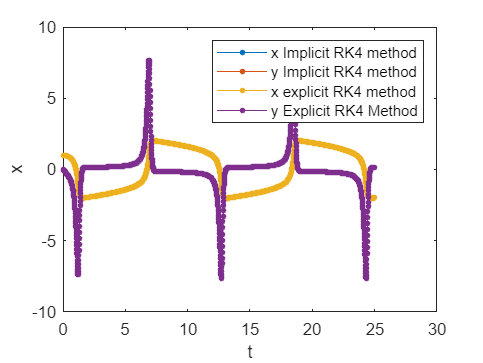

%Simulate using ERK4

%% ERK4 method
u=5;
f_1 = @(yRK4)(yRK4);
f_2 = @(xRK4,yRK4)(u*(1-xRK4^2)*yRK4-xRK4);


dt= 10^-2;
N = tFinal/dt;
tERK4 = zeros(N+1,1);
xERK4 = zeros(N,1);
yERK4 = zeros(N,1);
xERK4(1)=x0(1);
yERK4(1)=x0(2);

    for j = 2:N+1
        ButcherRK4=butchert(4);
        a21=ButcherRK4(2,2);
        a32=ButcherRK4(3,3);
        a43=ButcherRK4(4,4);
        c=ButcherRK4(:,1)';
        b1=ButcherRK4(5,2:end)';
        tERK4(j) = tERK4(j-1) + dt;
        
        K1x = f_1(yERK4(j-1));
        K1y = f_2(xERK4(j-1), yERK4(j-1));
        K2x = f_1(yERK4(j-1)+a21*dt*K1y);
        K2y = f_2(xERK4(j-1)+a21*dt*K1x, yERK4(j-1)+c(2)*dt*K1y);
        K3x = f_1(yERK4(j-1)+a32*dt*K2y);
        K3y = f_2(xERK4(j-1)+a32*dt*K2x, yERK4(j-1)+c(3)*dt*K2y);
        K4x = f_1(yERK4(j-1)+a43*dt*K3y);
        K4y = f_2(xERK4(j-1)+a43*dt*K3x, yERK4(j-1)+c(4)*dt*K3y);
        xERK4(j) = xERK4(j-1) + dt*(b1(1)*K1x+ b1(2)*K2x+b1(3)*K3x+b1(4)*K4x);
        yERK4(j) = yERK4(j-1) + dt*(b1(1)*K1y+ b1(2)*K2y+b1(3)*K3y+b1(4)*K4y);
    end

%Plotting
plot(tIRK4,xIRK4,'marker','.','markersize',10);
hold on
plot(tIRK4,yIRK4,'marker','.','markersize',10);
plot(tERK4,xERK4,'marker','.','markersize',10);
plot(tERK4,yERK4,'marker','.','markersize',10);
xlabel('t');
ylabel('x');
legend('x Implicit RK4 method','y Implicit RK4 method','x explicit RK4 method','y Explicit RK4 Method')